# Questão 3

Considerar as seguintes modulações:

- BPSK

- QPSK

- 8-PSK

- 16-QAM

- 64-QAM

**Critério de seleção**: maximização da eficiência espectral para um desempenho de probabilidade de erro limitante $P_e$.

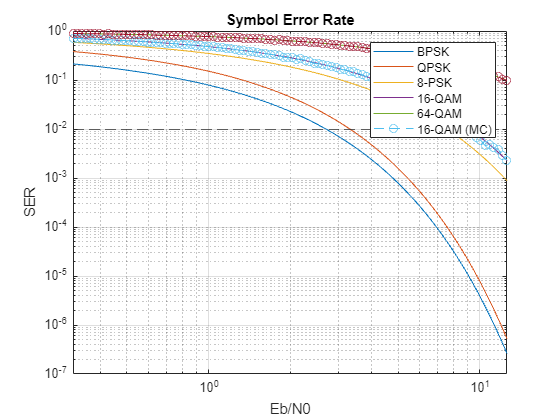

rng('default')

eb_n0 = logspace(-0.5, 1.1, 100);

% Valores teóricos
[~, bpsk_teorica] = berawgn(pow2db(eb_n0), 'psk', 2, 'nondiff');
[~, qpsk_teorica] = berawgn(pow2db(eb_n0), 'psk', 4, 'nondiff');
[~, psk8_teorica] = berawgn(pow2db(eb_n0), 'psk', 8, 'nondiff');
[~, qam16_teorica] = berawgn(pow2db(eb_n0), 'qam', 16);
[~, qam64_teorica] = berawgn(pow2db(eb_n0), 'qam', 64);

% Valores simulados por Monte Carlo
qam16_mc = m_qam(eb_n0, 16);
qam64_mc = m_qam(eb_n0, 64);

figure();
loglog(eb_n0, bpsk_teorica); hold on;
loglog(eb_n0, qpsk_teorica);
loglog(eb_n0, psk8_teorica);
loglog(eb_n0, qam16_teorica);
loglog(eb_n0, qam64_teorica); 
loglog(eb_n0, qam16_mc, 'LineStyle', '--', 'Marker', 'o');
loglog(eb_n0, qam64_mc, 'LineStyle', '--', 'Marker', 'o');
yline(0.01, 'LineStyle', '--');
hold off;
grid on;

title('Symbol Error Rate');
xlabel('Eb/N0');
ylabel('SER');
legend('BPSK', 'QPSK', '8-PSK', '16-QAM', '64-QAM', ...
    '16-QAM (MC)');